clear

% Load parameters
load_parameters;

% Define the simulation time step
dt = 0.01;

% Start recording how much time the simulation takes
tic

% Initialize variables for control loop
prev_error = 0;
integral = 0;
prev_t = 0;
z0 = params.z_eq + 0.02; % Initial condition for magnet position

% Pre-allocate arrays to store simulation results
tf = 100.0;
tSpan = linspace(0, tf, tf/dt); % Time vector with sampling rate of 100Hz
z_ref = params.z_eq + 0.02; % Reference position for control
dz_ref = 0; % Reference velocity for control
num_steps = tf * round(1/dt);
t_result = zeros(num_steps, 1); % Time vector to store simulation time
x_result = zeros(num_steps, 2); % Matrix to store magnet position and velocity
u_signal = zeros(num_steps, 1); % Control signal vector
error_sig = zeros(num_steps, 1); % Error signal vector

% Control loop
t_current = 0.0;
x_current = [z0; 0]; % Initial state vector [position; velocity]
for i = 1:num_steps
    % Calculate error
    error = z_ref - x_current(1);
    error_sig(i) = error;
    
    % Calculate control signal (not implemented yet, set to zero)
    u = 0.05 * (z_ref -  x_current(1));
    u_signal(i) = u;

    % Store current time and state
    t_result(i) = t_current;
    x_result(i, :) = x_current;
    
    % Update state using ODE integration
    [t_out, x_out] = ode15s(@(t, x) magnet_levitation_ode(x(1), x(2), u, params), [t_current t_current + dt], x_current);
    
    % Update current time and state for next iteration
    t_current = t_out(end);
    x_current = x_out(end, :);

end 

fprintf('Simulation time: %.2fs\n', toc) % toc stops the clock for computing the simulation time

Simulation time: 1.81s


### Plotting results

We plot the position of the center of the magnet to see the results of the simulation.

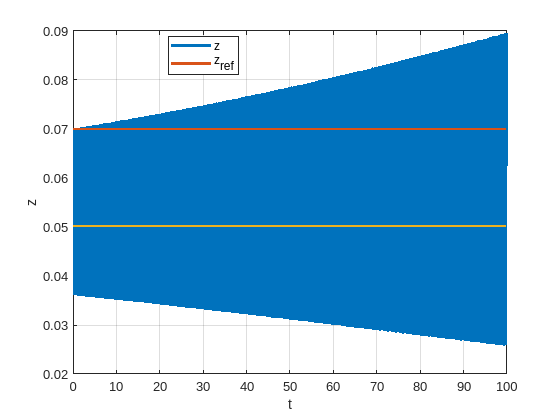

figure;
clf; grid on; hold on; box on;

plot(t_result, x_result(:, 1),'linewidth',2)
plot(t_result, z_ref * ones(num_steps,1),'linewidth',2)
plot(t_result, params.z_eq * ones(num_steps,1),'linewidth',2)

legend({'z','z_{ref}'},'location','best')
xlabel('t')
ylabel('z')

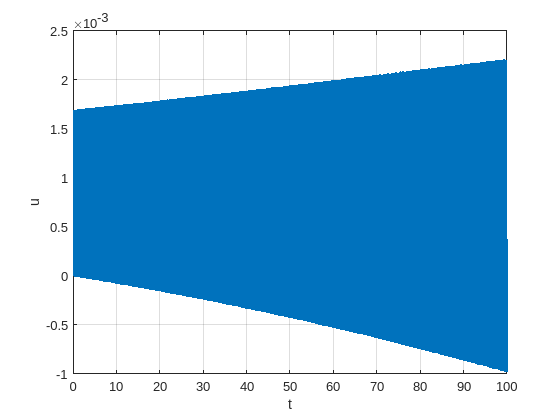

figure
clf; grid on; hold on; box on;

plot(t_result, u_signal,'linewidth',2)
xlabel('t')
ylabel('u')

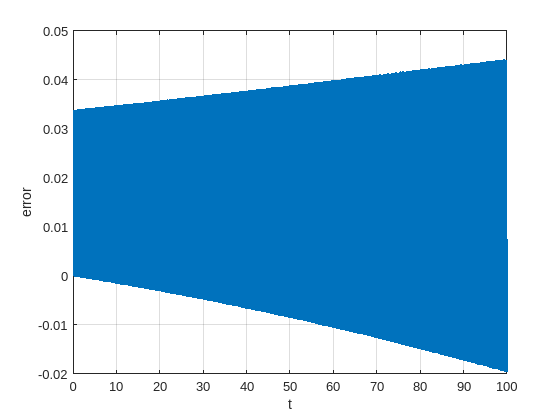

figure
clf; grid on; hold on; box on;

plot(t_result, error_sig,'linewidth',2)
ylabel('error')
xlabel('t')